#### `N foot position: `$r_{f,i}$

clear all; clc; close all;
N = 5;
foot_W = 0.12;
foot_H = 0.125;
foot_stride_y = 0.12;
foot_stride_x = 0.125;
is_left = false;
swingHeight = 0.1;

g = 9.807; 
delta_z_vrp = 0.68;
omega = sqrt(g/delta_z_vrp);
z_robot = 0.78;

t_step = 0.8;
t_sample = 0.01;
tDS = 0.3;
alpha = 0.5;
tSS = t_step - tDS;

traj_ds = struct('index', {}, 'xi_ds', {}, 'state', {});
traj_ss = struct('index', {}, 'xi_ss', {}, 'state', {});


for i=1:N+3
    if i == 1
        r_f_r(i,1) = 0;
        r_f_l(i,1) = 0;
    elseif i == N+3
        r_f_l(i, 1) = (foot_H + foot_stride_x)*(i-2);
        r_f_r(i,1) = (foot_H + foot_stride_x)*(i-2);
    elseif mod(i,2) == 0
        r_f_l(i,1) = (foot_H + foot_stride_x)*(i-1);
        r_f_r(i,1) = r_f_r(i-1,1);  
    else
        r_f_r(i,1) = (foot_H + foot_stride_x)*(i-1);
        r_f_l(i,1) = r_f_l(i-1,1);
    end
    r_f_l(i,2:3) = [(foot_W/2 + foot_stride_y/2) 0];
    r_f_r(i,2:3) = [-(foot_W/2 + foot_stride_y/2) 0];
end
r_vrp = r_f_r;
r_vrp(2:2:N+3, 1:2) = r_f_l(2:2:N+3,1:2);
if is_left == false
    temp = r_f_l;
    r_f_l = [1 -1 1].*r_f_r;
    r_f_r = [1 -1 1].*temp;
    r_vrp = r_f_l;
    r_vrp(2:2:N+3, 1:2) = r_f_r(2:2:N+3,1:2);
end
r_vrp(:,3) =+ delta_z_vrp;
r_vrp(end,:) = [1 0 1].*r_vrp(end,:);

#### 
$$\xi_{\textrm{ini}} \;,\xi_{\textrm{eos}\;\;} ,\xi_{\textrm{iniDS}} \;,\zeta_{\textrm{eoDS}}$$


[xi_ini, xi_eos] = Xi(N, r_vrp, omega, t_step);
[xi_iniDS, xi_dot_iniDS, xi_eoDS, xi_dot_eoDS] = Xi_DS(N, r_vrp, xi_ini, xi_eos, omega, t_step, tDS, alpha);

#### 
$$\xi_d \left(t\right)$$


for ith = 1:N+2
    indx =  int32((t_step*(ith-1)/t_sample));
    for t_loc = 0:t_sample:t_step - t_sample
        indx = indx + 1;
        xi_d(indx,:) = r_vrp(ith,:) + exp(omega*(t_loc-t_step))*(xi_eos(ith,:) - r_vrp(ith,:));
    end
end

#### 
$$\xi_{\textrm{ds}} \left(t\right)$$


for ith = 1:N+2
    indx = 0;
    if ith == 1
        T = (1-alpha)*tDS;
    else
        T = tDS;
    end
    P = [2/T^3  1/T^2 -2/T^3  1/T^2;
        -3/T^2 -2/T    3/T^2 -1/T;
         0      1      0      0;
         1      0      0      0];
    for t_loc = 0:t_sample:T
        indx = indx + 1;
        xi_d_ds(indx,:) = [t_loc^3 t_loc^2 t_loc 1]*P*[xi_iniDS(ith,:); xi_dot_iniDS(ith,:); xi_eoDS(ith,:); xi_dot_eoDS(ith,:)];
    end
    traj_ds(ith).xi_ds = xi_d_ds;
    traj_ds(ith).index = ith;
end

#### $\xi_d \left(t\right)$ `meged`

xi_d_mod = xi_d;
xi_d_mod(1:(tDS * (1-alpha) + t_sample) / t_sample, :) = traj_ds(1).xi_ds;
for i=1:N+1
    iniDS_indx = floor((i * t_step - alpha * tDS) / t_sample) + 1;
    eoDS_indx = floor((i * t_step + (1 - alpha) * tDS) / t_sample) + 1;
    xi_d_mod(iniDS_indx:eoDS_indx, :) = traj_ds(i+1).xi_ds;
end


#### `CoM trajectory`

x_com(1,:) = [0, 0, delta_z_vrp];
com_dot = [0, 0, 0];
for i = 2:length(xi_d_mod)
    x_com(i,:) = x_com(i-1,:) - t_sample*omega*(x_com(i-1,:) - xi_d_mod(i-1,:));
    com_dot(i, :) = (omega) * (xi_d_mod(i,:) - x_com(i,:)); %  (omega^2) was wrong
end

% x_com(1,:)=[0,0,delta_z_vrp];
% com_dot = [0, 0, 0];
% for index = 2:length(xi_d_mod)
%     xx = 0;
%     for t =1:index
%         inte = t_sample*xi_d_mod(t,:)* exp(t*t_sample*omega);
%         xx = inte + xx;
%     end
%     x_com(index,:) = (xx*omega + x_com(1,:))*exp(-index*t_sample*omega);
%     com_dot(index, :) = omega * (xi_d_mod(index,:) - x_com(index,:));
% end

#### `plot trajectories`

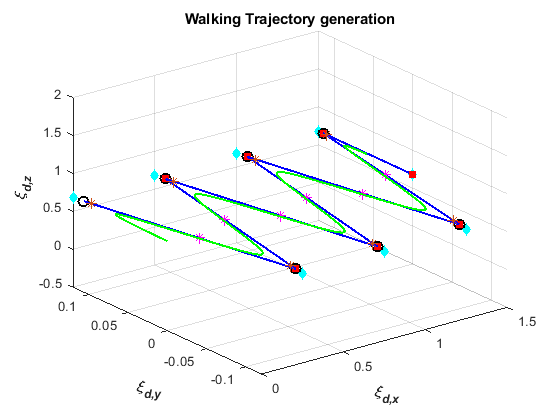

scatter3(r_vrp(:,1), r_vrp(:,2), r_vrp(:,3),50,'c','d',"filled")
hold on
scatter3(xi_ini(:,1), xi_ini(:,2), xi_ini(:,3),60,'o','MarkerEdgeColor','k','LineWidth',1.5)
scatter3(xi_eos(:,1), xi_eos(:,2), xi_eos(:,3),50,'r','s',"filled")

plot3(xi_d(:,1), xi_d(:,2), xi_d(:,3),'b','LineWidth', 1.5)

scatter3(xi_iniDS(2:end,1), xi_iniDS(2:end,2), xi_iniDS(2:end,3),50,'m','*')
scatter3(xi_eoDS(:,1), xi_eoDS(:,2), xi_eoDS(:,3),50,[.8 .3 .09],'*')

plot3(x_com(:,1), x_com(:,2), x_com(:,3),'g','LineWidth', 1.5)

xlabel('\bf \it \xi_{d,x}')
ylabel('\bf \it \xi_{d,y}')
zlabel('\bf \it \xi_{d,z}')
title('Walking Trajectory generation')
grid on

#### `seperation`

% SS
traj_ss(1).index = 1;
traj_ss(1).xi_ss = xi_d(((1-alpha)*tDS)/t_sample + 2:(t_step - alpha*tDS)/t_sample, :);
traj_ss(1).state = x_com(((1-alpha)*tDS)/t_sample + 2:(t_step - alpha*tDS)/t_sample, :);
traj_ss(1).state_dot = com_dot(((1-alpha)*tDS)/t_sample + 2:(t_step - alpha*tDS)/t_sample, :);
for i=1:N+1
    iniSS_indx = floor((i * t_step + (1 - alpha) * tDS) / t_sample) + 2;
    endSS_indx = floor(((i+1) * t_step - alpha * tDS) / t_sample);
    traj_ss(i+1).index = i+1;
    traj_ss(i+1).xi_ss = xi_d(iniSS_indx:endSS_indx, :);
    traj_ss(i+1).state = x_com(iniSS_indx:endSS_indx, :);
    traj_ss(i+1).state_dot = com_dot(iniSS_indx:endSS_indx, :);    
end

% DS
traj_ds(1).state = x_com(1:((1 - alpha) * tDS) / t_sample + 1, :);
traj_ds(1).state_dot = com_dot(1:((1 - alpha) * tDS) / t_sample + 1, :);

for i=1:N+1
    iniDS_indx = floor((i * t_step - alpha * tDS) / t_sample) + 1;
    endDS_indx = floor((i * t_step + (1 - alpha) * tDS) / t_sample) + 1;
    traj_ds(i+1).state = x_com(iniDS_indx:endDS_indx, :);
    traj_ds(i+1).state_dot = com_dot(iniDS_indx:endDS_indx, :);
end

#### `Steps Information Cell`

stepinfos = cell(1,N+1);

#### `Decreasing Robot's Height`

walkRdyPoints = [0      0; 
                 0      0; 
                 z_robot delta_z_vrp];  
timepoints = [0 0.5];
timevec = timepoints(1):t_sample:timepoints(end)-t_sample; 
[q, qd] = cubicpolytraj(walkRdyPoints, timepoints, timevec); 

% save data
stepinfo.index = 1; 
bodystate = [q(1,:); qd(1,:); q(2,:); qd(2,:); q(3,:); qd(3,:)]; % pos wrt world   
stepinfo.state = bodystate;
stepinfo.timevec = timevec; 
stepinfo.mode = 'doublesupport'; 
stepinfo.footposeleft = r_f_l(1,:)';
stepinfo.footposeright = r_f_r(1,:)';
if is_left
    stepinfo.footplant = r_f_l(1, :)';
else
    stepinfo.footplant = r_f_r(1, :)';
end
stepinfos{1} = stepinfo;

#### `Saving SS & DS Trajectory into stepinfos`

for i=1:N+2
    % double support
    stepinfo = struct;
    init_time = timevec(end) + t_sample;
    final_time = init_time + tDS;
    if i == 1
        final_time = init_time + tDS * (1-alpha);
    end
    timevec = init_time:t_sample:final_time;
    stepinfo.index = 2 * i;
    stepinfo.timevec = timevec;
    stepinfo.mode = 'doublesupport';
    if is_left
        if mod(i,2) ~= 0
            stepinfo.footplant = r_f_r(i+1,:)';
        else
            stepinfo.footplant = r_f_l(i+1,:)';        
        end
    else
        if mod(i,2) ~= 0
            stepinfo.footplant = r_f_l(i+1,:)';
        else
            stepinfo.footplant = r_f_r(i+1,:)';        
        end
    end

    stepinfo.footposeright = r_f_r(i,:)';
    stepinfo.footposeleft = r_f_l(i,:)';

    
    stepinfo.ksi = traj_ds(i).xi_ds;
    stepinfo.state([1,3,5], :) = traj_ds(i).state';
    stepinfo.state([2,4,6], :) = traj_ds(i).state_dot';
    stepinfos{2 * i} = stepinfo;
    
    % single support
    stepinfo = struct;
    init_time = timevec(end) + t_sample;
    final_time = init_time + tSS - 2*t_sample;
    timevec = init_time:t_sample:final_time;
    stepinfo.index = 2 * i + 1;
    stepinfo.timevec = timevec;
    if is_left
        if mod(i,2) ~= 0
            stepinfo.footplant = r_f_r(i+1,:)';
            stepinfo.mode = 'singlesupportright';
            stepinfo.footposeright = r_f_r(i+1,:)';
            swingfootpos0 = r_f_l(i, :);
            swingfootpos1 = r_f_l(i+1, :);
        else
            stepinfo.footplant = r_f_l(i+1,:)';
            stepinfo.mode = 'singlesupportleft';
            stepinfo.footposeleft = r_f_l(i+1,:)';
            swingfootpos0 = r_f_r(i, :);
            swingfootpos1 = r_f_r(i+1, :);
        end
    else
        if mod(i,2) ~= 0
            stepinfo.footplant = r_f_l(i+1,:)';
            stepinfo.mode = 'singlesupportleft';
            stepinfo.footposeleft = r_f_l(i+1,:)';
            swingfootpos0 = r_f_r(i, :);
            swingfootpos1 = r_f_r(i+1, :);
        else
            stepinfo.footplant = r_f_r(i+1,:)'; 
            stepinfo.mode = 'singlesupportright';
            stepinfo.footposeright = r_f_r(i+1,:)';
            swingfootpos0 = r_f_l(i, :);
            swingfootpos1 = r_f_l(i+1, :);
        end
    end
  
    stepinfo.ksi = traj_ss(i).xi_ss;
    stepinfo.state([1,3,5], :) = traj_ss(i).state';
    stepinfo.state([2,4,6], :) = traj_ss(i).state_dot';
    

    [qswing, dqswing, ddqswing] = getSwingFootTraj(swingfootpos0', swingfootpos1', swingHeight, ...
                                init_time, final_time,t_sample);
    stepinfo.swing([1, 3, 5], :) = qswing;
    stepinfo.swing([2, 4, 6], :) = dqswing;
    stepinfos{2 * i + 1} = stepinfo;
end

#### `functions definition`

function [xi_ini, xi_eos] = Xi(N, r_vrp, omega, t_step)
xi_eos = zeros(N+2,3);
xi_eos(N+2,:) = r_vrp(end,:);
for i = N+1:-1:1
        xi_eos(i,:) = r_vrp(i+1,:) + (exp(-omega*t_step))*(xi_eos(i+1,:)-r_vrp(i+1,:));
        xi_ini(i+1,:) = xi_eos(i,:);
end
xi_ini(1,:) = r_vrp(i,:) + (exp(-omega*t_step))*(xi_eos(i,:)-r_vrp(i,:));
end


function [xi_iniDS, xi_dot_iniDS, xi_eoDS, xi_dot_eoDS] = Xi_DS(N, r_vrp, xi_ini, xi_eos, omega, t_step, tDS, alpha)
for i = 1:N+2
    xi_eoDS(i,:) = r_vrp(i,:) + exp(omega*((1-alpha)*tDS))*(xi_ini(i,:) - r_vrp(i,:));
    xi_dot_eoDS(i,:) = omega*exp(omega*((1-alpha)*tDS))*(xi_ini(i,:) - r_vrp(i,:));
    if i == 1
        xi_iniDS(i,:) = r_vrp(i,:) + exp(-omega*t_step)*(xi_eos(i,:) - r_vrp(i,:));    
        xi_dot_iniDS(i,:) = omega*exp(-omega*(t_step))*(xi_eos(i,:) - r_vrp(i,:));
    else
        xi_iniDS(i,:) = r_vrp(i-1,:) + exp(-omega*(alpha*tDS))*(xi_ini(i,:) - r_vrp(i-1,:));    
        xi_dot_iniDS(i,:) = omega*exp(-omega*(alpha*tDS))*(xi_ini(i,:) - r_vrp(i-1,:));
    end
end
end